# Seminarski zadatak

## Uvod

### U zadatku je potrebno:

- Načiniti simulacijski model **nelinearnog **sustava u Simulinku i simuliratu odziv.

- Zatvoriti povratnu vezu po položaju tereta (uzeti u obzir koeficijent povratne veze) i simulirati ponašanje sustava za pomak tereta iznosa 1 rad u lijevu i desnu stranu od srednjeg položaja motora. Prikazati na slikama ponašanje u vremenu za slijedeće varijable: referencu i ostvareni kut zakreta tereta, kutnu brzinu tereta, struju prop. ventila, pomak klipa prop ventila, protoke kroz prop. ventil, te tlakove u komorama motora. Pojačanjem regulatora ostvariti prihvatljiv odziv sustava.

### Opis zadatka

#### Slika hidrauličke sheme

Na slici je prikazan rotacijski hidraulički sustav, koji se sastoji od hidrauličkog motora upravljanog proporcionalnim ventilom, pri čemu se upravlja kutem zakreta tereta.

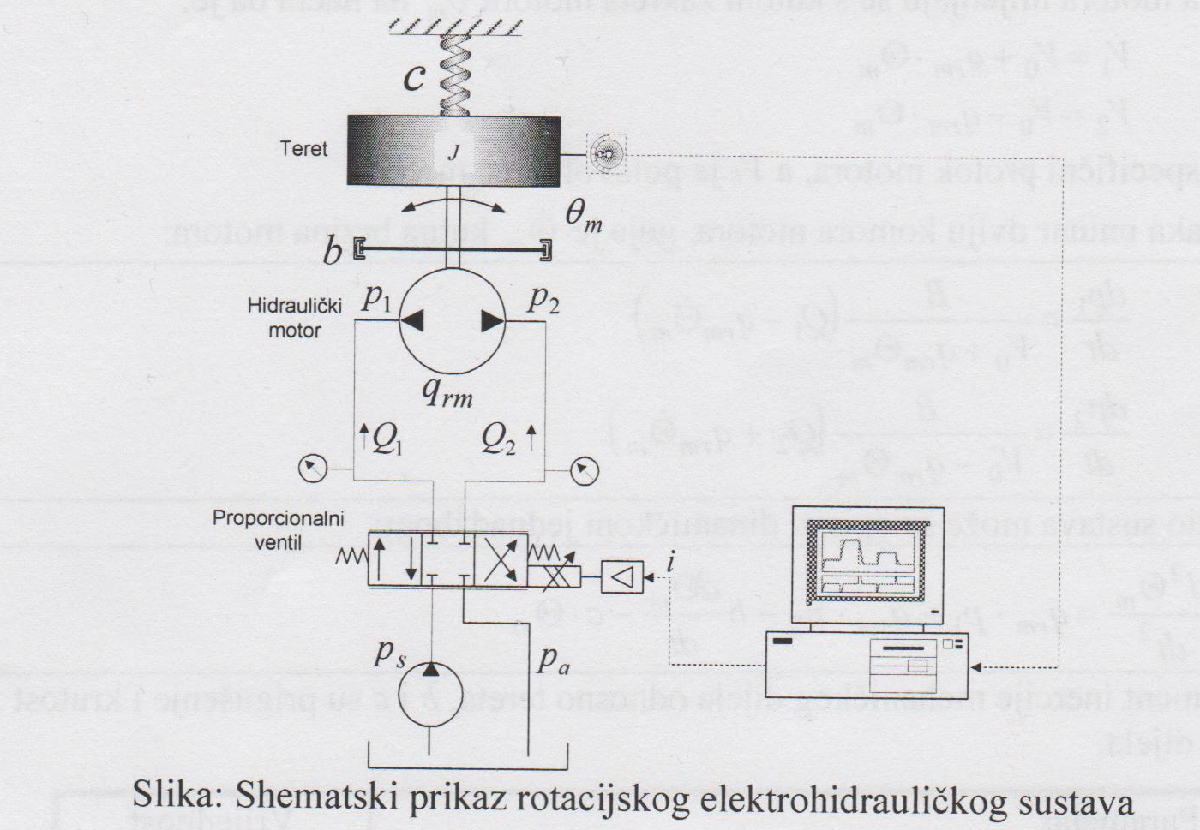

#### Proporcionalni ventil

Dinamika proporcionalnog ventila može se opisati prijenosnom funkcijom P1 člana:

$\frac{y_v(s)}{i(s)} = \frac{K_v}{\frac{1}{\omega_v}+1}$        (1)

$y_v$ - pozicija klipa proporcionalnog ventila, m

$i$ - ulazna struja proporcionalnog ventila, A

$K_v$ - koeficijent pojačanja proporcionalnog ventila, m/A

$\omega_v$ - vlastita frekvencija proporcionalnog centila, rad/s

Jednadžbe protoka kroz proporcionalni ventil iznose:

$Q_1(y_v,p_1)=\begin{cases}
y_v*\sqrt{|p_s-p_1|}*sign(p_s-p_1), & \text{za } y_v\geq0\\
y_v*\sqrt{|p_1-p_s|}*sign(p_1-p_s), & \text{za } y_v<0
\end{cases}$        (2)

$Q_2(y_v,p_2)=\begin{cases}
y_v*\sqrt{|p_2-p_a|}*sign(p_2-p_a), & \text{za } y_v\geq0\\
y_v*\sqrt{|p_s-p_s2}*sign(p_s-p_2), & \text{za  } y_v<0
\end{cases}$        (3)

$p_1$ - tlak u lijevoj komori motora, Pa

$p_2$ - tlak u desnoj komori motora, Pa

$p_s$ - tlak napajanja, Pa

$p_a$ - tlak spremnika, Pa

Pretpostavlja se da su tlakovi napajanja i spremnika konstantne veličine

Protoci $Q_1$ i $Q_2$ su:

$Q_1(y_v,p_1)=-Q_2(y_v,p_2)$        (4)

#### Hidraulički motor

Za motor vrijedi slijedeća hidrodinamička jednadžba:

$\frac{V}{B}*\frac{dp}{dt}+\frac{dV}{dt}=Q$        (5)

$B$ - modul stišljivosti ulja

$V$- volumen motora, $m^3$

$p$ - tlak motora, Pa

$Q$ - protok motora, $m^3/s$

$ \theta_m$ - kut zakreta motora, rad

Volumeni dviju komora motora mijenjaju se s kutom zakreta motora $ \theta_m$:

$V_1=V_0+q_{rm}*\dot{\theta_m}$        (6)

$V_2=V_0-q_{rm}*\dot{\theta_m}$        (7)

$q_{rm}$ - specifični protok motora, $m^3/rad$

$V_0$ - poluvolumen motora, $m^3$

$\dot{\theta_m}$ - kutna brzina motora, rad/s

Ponašanje tlaka unutar dviju komora motora:

$\frac{dp_1}{dt}=\frac{B}{V_0+q_{rm}\theta_m}(Q1-q_{rm}\dot{\theta_m})$        (8)

$\frac{dp_2}{dt}=\frac{B}{V_0-q_{rm}\theta_m}(Q1+q_{rm}\dot{\theta_m})$        (9)

Mehanički dio sustava može se opisati dinamičkom jednadžbom:

$J*\frac{d^2\theta_m}{dt^2}=q_{rm}*p_1-q_{rm}*p_2-b\frac{d\theta_m}{dt}-c*\theta_m$        (10)

$J$ - moment inercije mehaničkog dijela (tereta), $kgm^2$

$b
$ - prigušenja mehaničkog dijela, Nms/rad

$c$ - krutost mehaničkoh dijela, Nm/rad

### Parametri sustava

global Kv omegav ps pa B V0 qrm J b c Km Kr
Kv = 5.55e-7;   % Koeficijent pojačanja proporcionalnog ventila 
omegav = 113;   % Vlastita frekvencija proporcionalnog ventila
ps = 100e5;     % Tlak napajanja
pa = 1e5;       % Tlak spremnika
B = 1350e6;     % Modul stišljivosti ulja
V0 = 150e-6;    % Poluvolumen motora
qrm = 25.6e-6;  % Specifični protok motora
J = 0.00156;    % Moment inetcije tereta
b = 0.5;        % Koeficijent prigušenja tereta (trenje)
c = 150;        % Koeficijent elastičnosti tereta
Km = 1;         % Koeficijent povratne veze
Kr = 1;         % Pojačanje P regulatora

## Simulink model

### Simulink shema

out = sim("seminar_simulink0.slx");

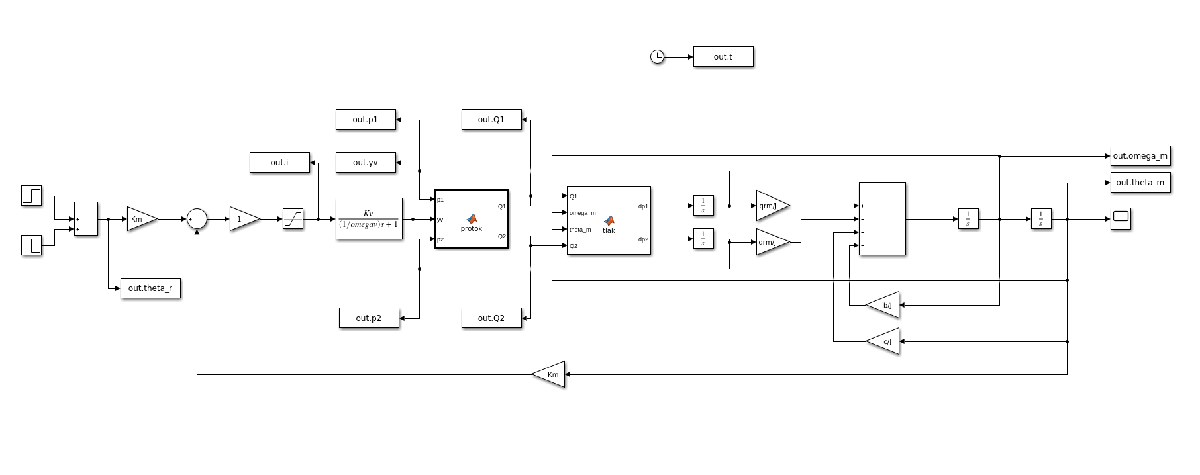

### Matlab funkcije u Simulinku

#### Matlab funkcija protok

Funkcije protoka proporcionalnog ventila (2) i (3) su implementirane u Simulinku matlab funkcijom:

#### Matlab funkcija tlak

Funkcije ponašanja tlaka unutar dvije komore motora (8) i (9) su implementirane u Simulinku matlab funkcijom:

## Simulacijski rezultati

### Pobuda i odziv

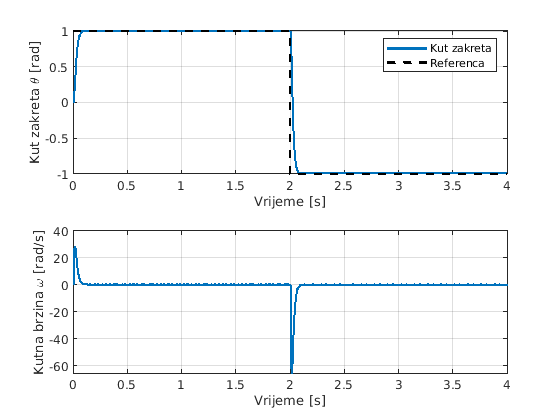

figure
subplot(2,1,1);
plot(out.t, out.theta_m, 'LineWidth', 2);
hold on
plot(out.t, out.theta_r, 'k--', 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kut zakreta \theta [rad]');
legend('Kut zakreta', 'Referenca');

subplot(2,1,2);
plot(out.t, out.omega_m, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Kutna brzina \omega [rad/s]');

### Pozicija proporcionalnog ventila

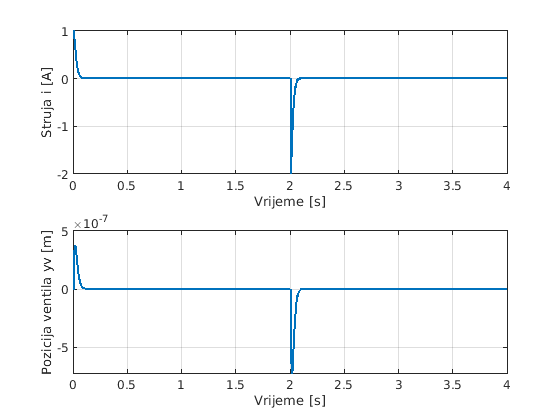

figure
subplot(2,1,1);
plot(out.t, out.i, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Struja i [A]');

subplot(2,1,2);
plot(out.t, out.yv, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Pozicija ventila yv [m]');

### Protok proporcionalnog ventila

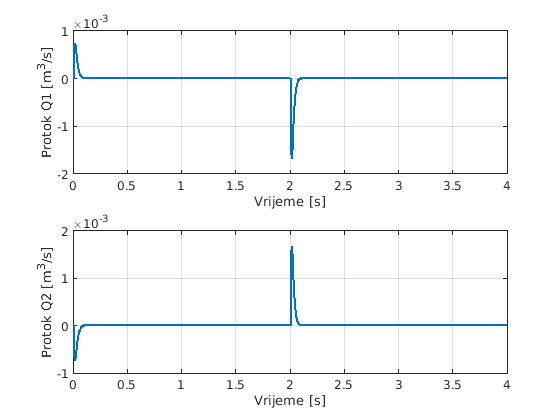

figure
subplot(2,1,1);
plot(out.t, out.Q1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q1 [m^3/s]');

subplot(2,1,2);
plot(out.t, out.Q2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Protok Q2 [m^3/s]');

### Tlakovi u komorama motora

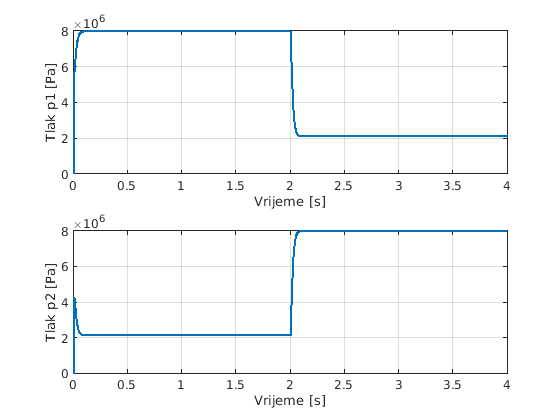

figure
subplot(2,1,1);
plot(out.t, out.p1, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p1 [Pa]');

subplot(2,1,2);
plot(out.t, out.p2, 'LineWidth', 2);
grid on
xlabel('Vrijeme [s]');
ylabel('Tlak p2 [Pa]');

## Zaključak

## Prilog: